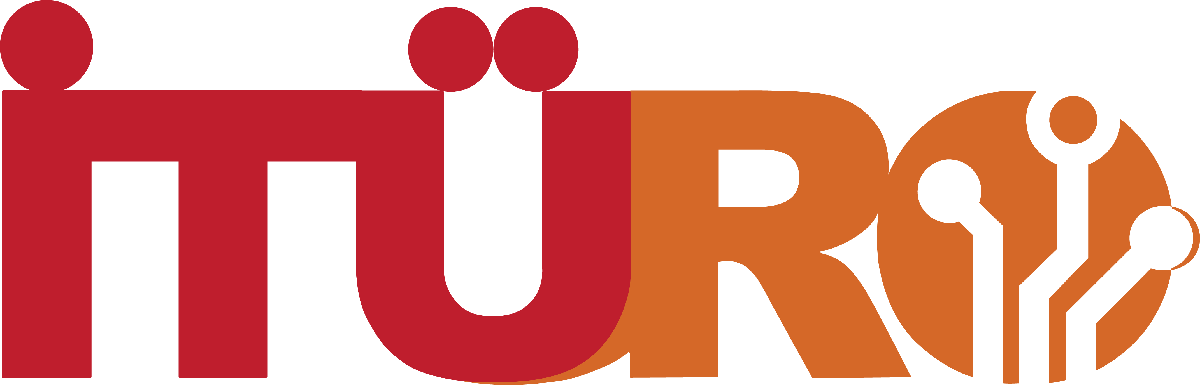

# **ALGOLAB 2023**

*HAZIRLAYAN: BURAK ÖZPOYRAZ - burakozpoyraz@gmail.com*

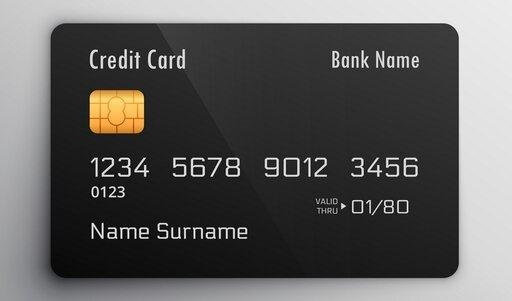

## KREDİ KARTI

Bir yazılım şirketi *American Express*, *Mastercard* ve *VISA* kredi kartları için kredi kartı numarası üreten bir yazılım geliştirmek için bir yazılımcı işe almıştır. Bu proje için araştırma yapan yazılımcı, bir kredi kartı numarasının geçerliliğinin [Luhn algoritması](https://en.wikipedia.org/wiki/Luhn_algorithm) ile kontrol edilebileceğini öğrenmiştir. Luhn algoritmasının adımlarını iyice öğrenmek için de örnek bir kredi kartı numarası olan $\matrix{
4556 & 7375 & 8689 & 9855
}$ üzerinde test yapmıştır ve adımları aşağıdaki gibi uygulamıştır:

- Kredi kartı numarasının son basamağı çıkartılır: $\matrix{
4 & 5 & 5 & 6 & 7 & 3 & 7 & 5 & 8 & 6 & 8 & 9 & 9 & 8 & 5
}$

- Numaranın basamakları sondan başa doğru dizilir: $\matrix{
5 & 8 & 9 & 9 & 8 & 6 & 8 & 5 & 7 & 3 & 7 & 6 & 5 & 5 & 4
}$

- Tek indisli basamaklar 2 ile çarpılır: $\matrix{
10 & 8 & 18 & 9 & 16 & 6 & 16 & 5 & 14 & 3 & 14 & 6 & 10 & 5 & 8	
}$

- 9'dan büyük olan basamaklardan 9 çıkartılır: $\matrix{
1 & 8 & 9 & 9 & 7 & 6 & 7 & 5 & 5 & 3 & 5 & 6 & 1 & 5 & 8	
}$

- Tüm basamaklar toplanır: $1+8+9+9+7+6+7+5+5+3+5+6+1+5+8=85$

- Elde edilen toplamın $10$'a bölümünden kalan hesaplanır: $5$

Eğer son adımda elde edilen kalan, ilk adımda çıkartılan son basamağa eşitse kredi kartı numarası geçerlidir. Yukarıdaki örnekte verilen kredi kartı numarası da geçerli bir numaradır. Yazılımcı, bu algoritmadan yola çıkarak yukarıda verilen kredi kartları için numaralar üreten bir program yazmak istemektedir. Bunun için çalıştığı firma tarafından kredi kartlarıyla ilgili aşağıdaki bilgileri almıştır:

- *American Express* kredi kartlarının numaraları $15$ basamaklıdır ve $34$ ile başlar.

- Mastercard kredi kartlarının numaraları $16$ basamaklıdır ve $52$ ile başlar.

- VISA kredi kartlarının numaraları da $16$ basamaklıdır ve $4$ ile başlar.

Tüm bu bilgiler ışığında yazılımcının görevi, `CC` ile verilen bir kredi kartı için geçerli bir kredi kartı numarası üreten programı yazmaktır. Burada `CC` farklı kredi kartları için aşağıdaki değerleri alabilir:

CC = "AE" % American Express
CC = "MC" % Mastercard
CC = "VS" % VISA

**FONKSİYON GİRDİLERİ**

- `CC (1x1 string)`

**FONKSİYON ÇIKTILARI**

- `CC_num (1x15 double veya 1x16 double)`

**ÖRNEK-1**

CC = "AE";
CC_num = [3 4 4 0 3 1 7 3 5 1 6 2 6 6 9];

**ÖRNEK-2**

CC = "MC";
CC_num = [5 2 4 0 2 9 1 8 5 9 0 4 1 9 0 9];

**ÖRNEK-3**

CC = "VS";
CC_num = [4 8 8 0 3 2 8 4 9 1 2 1 1 8 5 8];